## Pade

clear;close all;clc

Head

wn = 50; % head natural frequency [rad/s]
z = 1.2; % head damping ratio []
% I_h = 0.0895*(10^(-3))^(3); % head inertia about rotation point [kg*m^2]
I_h = 0.2*5.2e-13;
k_h = wn^(2)*I_h; % head stiffness [N*m/rad]
cc = 2*sqrt(k_h*I_h); % head critical damping [N*m*s/rad]
c_h = z*cc; % head damping [N*m*s/rad]
% I_h = 1; % head inertia about rotation point [kg*m^2]
% k_h = 1; % head stiffness [N*m/rad]
% c_h = 1; % head damping [N*m*s/rad]
Ph = tf(1,[I_h c_h k_h])


Ph =
 
                  
                 1
                  
  --------------------------------
                                  
  1.04e-13 s^2 + 1.248e-11 s      
                                  
                         + 2.6e-10
                                  
 
Continuous-time transfer function.



Body

I_b = 5.2e-13; % head inertia about rotation point [kg*m^2]
k_b = 0; % body stiffness [N*m/rad]
c_b = 5.2e-13; % body damping [N*m*s/rad]
% I_b = 1; % body inertia about rotation point [kg*m^2]
% k_b = 1; % body stiffness [N*m/rad]
% c_b = 1; % body damping [N*m*s/rad]
Pb = tf(1,[I_b c_b k_b])


Pb =
 
             1
  -----------------------
  5.2e-13 s^2 + 5.2e-13 s
 
Continuous-time transfer function.



System

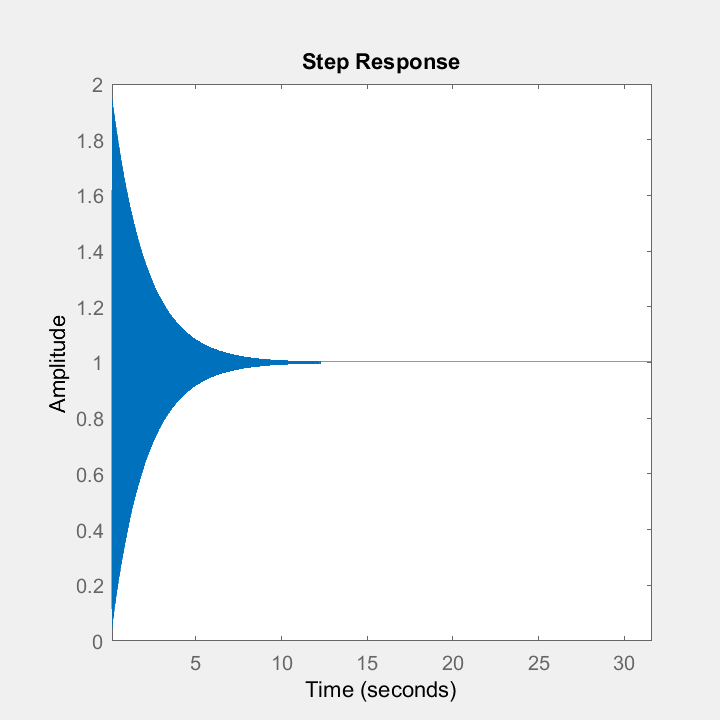

Ch = 0.1;
Th = tf(1,'InputDelay',10e-3);
Cb = 0.00001;
Tb = tf(1,'InputDelay',40e-3);

% Gb_free  = Cb*Pb/(1 + Ch*Ph*Th + Cb*Pb*Tb);
% Gb_fixed = Cb*Pb/(1 + Ch*0*Th + Cb*Pb*Tb);

FIG = figure (1) ; clf ; hold on
FIG.Visible = 'on';
FIG.Units = 'inches';
FIG.Position = [2 2 5 5];
% delay = linspace(0,0.1,5)';
delay = 0;
for dd = 1:length(delay)
    Tb = tf(1,'InputDelay',delay(dd));
    Gb_fixed = Cb*Pb/(1 + Ch*0*Th + Cb*Pb*Tb);
    % bode(pade(Gb_fixed,5))
    step(Gb_fixed)
end
xlim(10.^[-1 1.5])

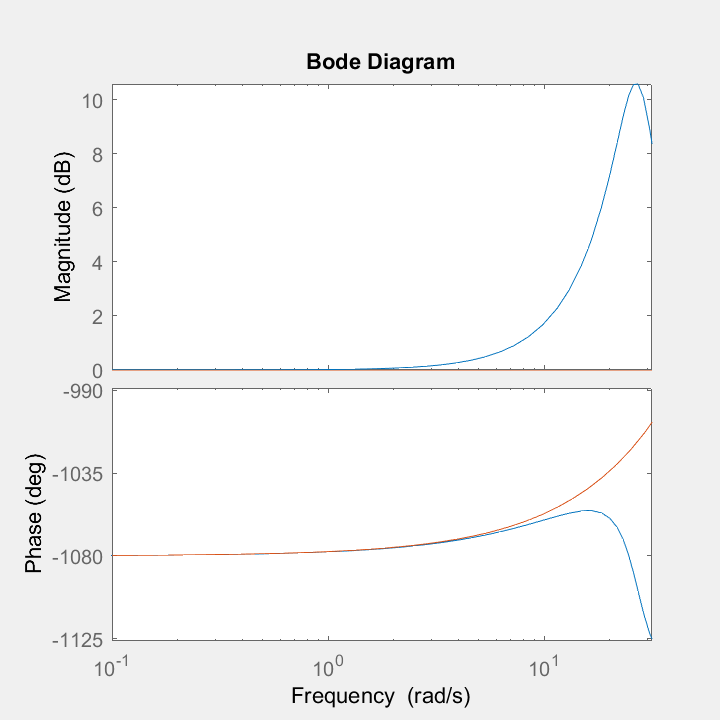


Ch = 0.1;
Th = tf(1,'InputDelay',10e-3);
Cb = 0.1;
Tb = tf(1,'InputDelay',40e-3);

Gb_free  = Cb*Pb/(1 + Ch*Ph*Th + Cb*Pb*Tb);
Gb_fixed = Cb*Pb/(1 + Ch*0*Th + Cb*Pb*Tb);

FIG = figure (2) ; clf ; hold on
FIG.Visible = 'on';
FIG.Units = 'inches';
FIG.Position = [2 2 5 5];
bode(pade(Gb_free,5))
bode(pade(Gb_fixed,5))
xlim(10.^[-1 1.5])

## Symbolic

clear;close all;clc
syms s omega
assume(s>=0)

Head

% wn = 50; % head natural frequency [rad/s]
% z = 1.2; % head damping ratio []
% I_h = 0.0895*(10^(-3))^(3); % head inertia about rotation point [kg*m^2]
% k_h = wn^(2)*I_h; % head stiffness [N*m/rad]
% cc = 2*sqrt(k_h*I_h); % head critical damping [N*m*s/rad]
% c_h = z*cc; % head damping [N*m*s/rad]
I_h = 1; % head inertia about rotation point [kg*m^2]
k_h = 1; % head stiffness [N*m/rad]
c_h = 1; % head damping [N*m*s/rad]

Body

% I_b = 5.2e-13; % head inertia about rotation point [kg*m^2]
% k_b = 0; % body stiffness [N*m/rad]
% c_b = 5.2e-13; % body damping [N*m*s/rad]
I_b = 1; % body inertia about rotation point [kg*m^2]
k_b = 1; % body stiffness [N*m/rad]
c_b = 1; % body damping [N*m*s/rad]

System

Ph = vpa(1/(I_h*s^(2) + c_h*s + k_h),2)

$$Ph = \frac{1}{s^{2}+s+1.0}$$

Ch = 1;
Dh = exp(-s*1000e-3);

Pb = vpa(1/(I_b*s^(2) + c_b*s + k_b),2)

$$Pb = \frac{1}{s^{2}+s+1.0}$$

Cb = 1;
Db = exp(-s*1000e-3);

Gb_free = vpa(simplify(expand(Pb*Cb/(1 + Ph*Ch*Dh + Pb*Cb*Db))),2)

$$Gb\_free = \frac{{\mathrm{e}}^{s}}{{\mathrm{e}}^{s}+s^{2}\,{\mathrm{e}}^{s}+s\,{\mathrm{e}}^{s}+2.0}$$

Gb_free = vpa(simplify(expand(subs(Gb_free,s,i*omega))),2);

ww = logspace(-2,3,5000)';

Gb_free_num = double(subs(Gb_free,omega,ww));

Gb_fixed = vpa(simplify(expand(Pb*Cb/(1 + Pb*Cb*Db))),2)

$$Gb\_fixed = \frac{{\mathrm{e}}^{s}}{{\mathrm{e}}^{s}+s^{2}\,{\mathrm{e}}^{s}+s\,{\mathrm{e}}^{s}+1.0}$$

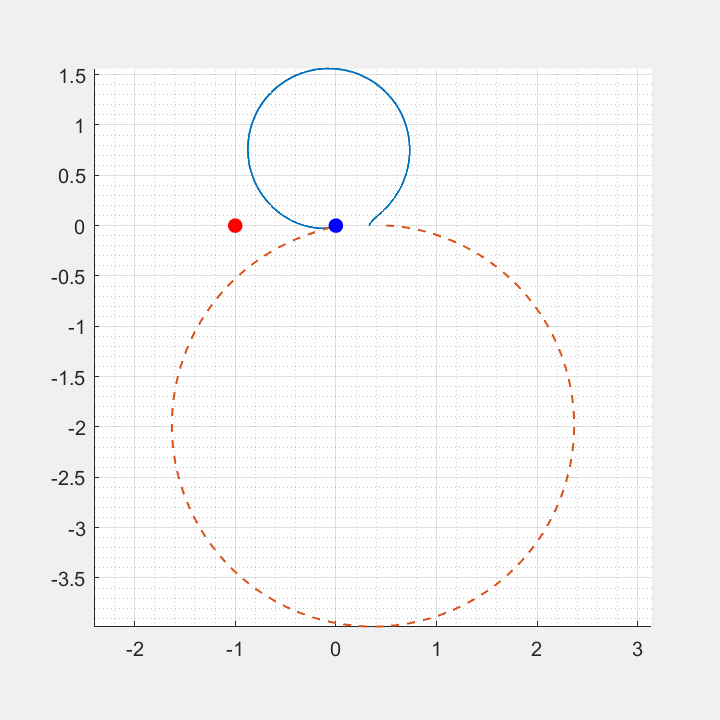

Gb_fixed = vpa(simplify(expand(subs(Gb_fixed,s,i*omega))),2);

Gb_fixed_num = double(subs(Gb_fixed,omega,ww));

FIG = figure (1) ; clf ; hold on ; grid on ; grid minor
FIG.Visible = 'on';
FIG.Units = 'inches';
FIG.Position = [2 2 5 5];
plot(real(Gb_free_num),imag(Gb_free_num),'LineWidth',1)
plot(real(Gb_fixed_num),imag(Gb_fixed_num),'--','LineWidth',1)
plot(0,0,'.b','MarkerSize',25)
plot(-1,0,'.r','MarkerSize',25)
axis equal
pbaspect([1 1 1])

% axis(1*[-1 1 -1 0.2])










